# REM & COMSOL Comparison

## REM Information

### Uniform Beam

#### Flexural REM

% --- Predicted Models ---
M = 40;              % Number of elements
Ns = 4;              % Number of sensors
fs = 2000;           % Sampling frequency, [Hz]
dt = 1/fs;    % Time resolution, [s]
% --- Define any material properties ---
% Flexural Rigidity, [Pa*m^2]
EI0 = 1 * 1e3*ones(1,M);
% Linear mass density, [kg/m]
mu0 = 1*ones(1,M);
% ---
sigFig = 4;
T = 1;               % Duration, [s]
% T = 10;
dx = 5 * 10^(-sigFig);     
x = 0:dx:1-dx;
% Sensor locations relative to L
SLocs = round(linspace((1/Ns),...
                        1-(1/Ns),...
                        Ns),sigFig-1);
StrainTF = false;
normalize = true;
magnitude = true;

% --- Flexural ---
% Select the boundary conditions to define the REM
BCcase = "Clamped-Free";
nmax = 3;
phiU_n = zeros(length(x),nmax);
omegaU_n = zeros(M,nmax);
% elapsedTime = zeros(50,1);
% for ii = 1:length(elapsedTime)
% tic
for n = 1:nmax
% Get time series response from t=0:T-dt
[t,yt,~,~,phi_elem,omega_elem] = FlexuralBending_REM(M,fs,...
                                    T=T,...
                                    dx=dx,...
                                    n=n,...
                                    EI=EI0,...
                                    mu=mu0,...
                                    BCcase=BCcase,...
                                    normalize=normalize,...
                                    StrainTF=StrainTF,...
                                    SLocs=SLocs);
phiU_n(:,n) = phi_elem(:);
omegaU_n(:,n) = omega_elem.';
end
% elapsedTime(ii) = toc;
% end

### Split Beam

#### Flexural REM

% --- Predicted Models ---
M = 40;              % Number of elements
Ns = 4;              % Number of sensors
fs = 2000;           % Sampling frequency, [Hz]
dt = 1/fs;    % Time resolution, [s]
% --- Define any material properties ---
% Flexural Rigidity, [Pa*m^2]
EI0 = 1 * 1e3*ones(1,M);
EI0(21:end) = 5000;
% Linear mass density, [kg/m]
mu0 = 1*ones(1,M);
% mu0(21:end) = 2;
% ---
sigFig = 4;
T = 1;               % Duration, [s]
% T = 10;
dx = 5 * 10^(-sigFig);     
x = 0:dx:1-dx;
% Sensor locations relative to L
SLocs = round(linspace((1/Ns),...
                        1-(1/Ns),...
                        Ns),sigFig-1);
StrainTF = false;
normalize = true;
magnitude = false;

% --- Flexural ---
% Select the boundary conditions to define the REM
BCcase = "Clamped-Free";
nmax = 3;
phiS_n = zeros(length(x),nmax);
omegaS_n = zeros(M,nmax);

% elapsedTime = zeros(50,1);
% for ii = 1:length(elapsedTime)
% tic
for n = 1:nmax
% Get time series response from t=0:T-dt
[t,yt,~,~,phi_elem,omega_elem] = FlexuralBending_REM(M,fs,...
                                    T=T,...
                                    dx=dx,...
                                    n=n,...
                                    EI=EI0,...
                                    mu=mu0,...
                                    BCcase=BCcase,...
                                    normalize=normalize,...
                                    StrainTF=StrainTF,...
                                    SLocs=SLocs);
phiS_n(:,n) = phi_elem(:);
omegaS_n(:,n) = omega_elem.';
end
% elapsedTime(ii) = toc;
% end

## COMSOL Results

path = fullfile(pwd,'COMSOL Results');
fileU = 'CantileverBeam_Uniform.txt';
fileS = 'CantileverBeam_Split Beam_uniform mass.txt';

phi_CU = readmatrix(fullfile(path,fileU));
phi_CU = sortrows(phi_CU,1);
x_phi_CU = phi_CU(:,1);
phi_CU = [phi_CU(:,3),phi_CU(:,4),phi_CU(:,5)];

phi_CS = readmatrix(fullfile(path,fileS));
phi_CS = sortrows(phi_CS,1);
x_phi_CS = phi_CS(:,1);
phi_CS = [phi_CS(:,3),phi_CS(:,4),phi_CS(:,5)];

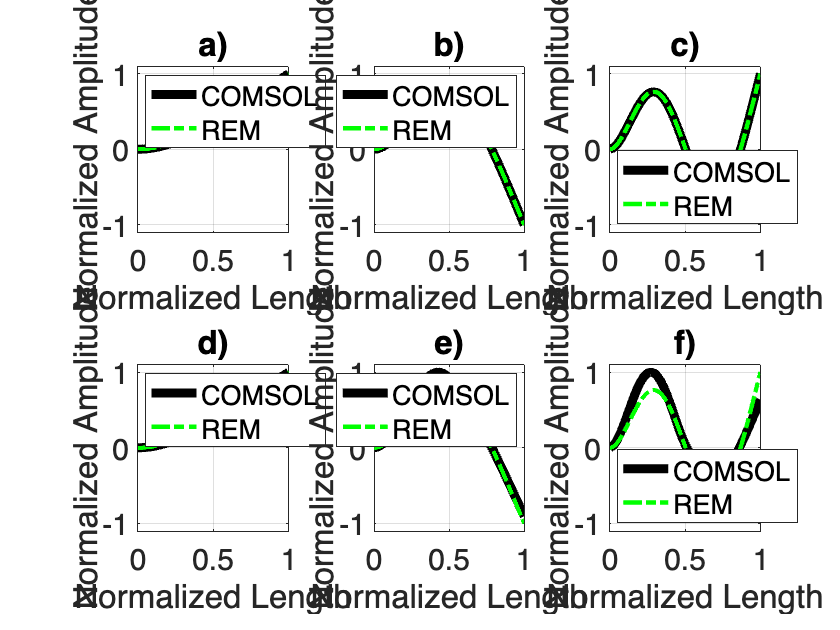

SetPlotDefaults(FontSize=24)

% figure
% subplot(2,2,1)
% plot(x,phiU_n,'o-')
% subplot(2,2,3)
% plot(x,phiS_n,'o-')
% subplot(2,2,2)
% plot(x_phi_CU,phi_CU,'o-')
% subplot(2,2,4)
% plot(x_phi_CS,phi_CS,'o-')
% figure
% for ii = 1:3
% subplot(1,3,ii)
% plot(x_phi_CU,phi_CU(:,ii)/max(abs(phi_CU(:,ii))),'k-',LineWidth=lw1)
% hold on
% plot(x,phiU_n(:,ii)/max(abs(phiU_n(:,ii))),'g-.',LineWidth=lw2)
% hold off
% ylim([-1.1,1.1])
% end
% figure
% for ii = 1:3
% subplot(1,3,ii)
% plot(x_phi_CS,phi_CS(:,ii)/max(abs(phi_CS(:,ii))),'k-',LineWidth=lw1)
% hold on
% plot(x,phiS_n(:,ii)/max(abs(phiS_n(:,ii))),'g-.',LineWidth=lw2)
% hold off
% ylim([-1.1,1.1])
% end
plotCompare(x, phiU_n, phiS_n, x_phi_CU, phi_CU, phi_CS)

% plotCompare(x, phiU_n, phiS_n, x, phiS_n, phiU_n)

## Beam 2

### REM Information

#### Variable Element Lengths and Spatial Resolution

% --- Non-uniform Spatial Sampling along x ---
% Spatial resolution of each element
dx = 1e-3 * [1, 0.5, 0.1, 0.5,...
             1, 0.5, 0.1, 0.5,...
             1, 0.5, 0.1, 0.5,...
             1];                    % Non-uniform resolution
% Length of individual elements
Lx = 1e-2 * [16.5, 0.45, 0.1, 0.45, ...
             12.0, 0.45, 0.1, 0.45,...
             19.0, 0.45, 0.1, 0.45, ...
             49.5];                 % Non-uniform length
% Get x-values
[X,x_elem,x2] = GetNonUniformXVals(dx,Lx);

#### Model Parameters

% --- Predicted Models ---
M = length(Lx);      % Number of elements
Ns = 4;              % Number of sensors
fs = 2000;           % Sampling frequency, [Hz]
dt = 1/fs;    % Time resolution, [s]
T = 1;               % Duration, [s]
mu0 = 1*ones(1,M);
% --- Sensor locations relative to L ---
SLocs = round([0.20 0.45 0.70 0.95],2); % SensorConfigB
% --- Damage locations relative to L ---
DLocs = [0.17 0.30 0.50];
% --- Model Output ---
StrainTF = false;
normalize = true;
magnitude = false;
REM = "Flex";
% Define element where fault occurs
fault_Locs = [3 7 11];
% Define change in EI and root EI-values
delta_EI = [0.75, 0.75, 0.75];
EI0 = 1e3 * ones(1,M);

% --- Flexural ---
% Select the boundary conditions to define the REM
BCcase = "Clamped-Free";
nmax = 3;

% elapsedTime = zeros(50,1);
% for ii = 1:length(elapsedTime)
% tic
for n = 1:nmax
% Get time series response from t=0:T-dt
[~,~,~,~,phi_elem,~] = FlexBend_REM_General(X,x_elem,fs,...
                                    T=T,...
                                    n=n,...
                                    EI=EI0,...
                                    mu=mu0,...
                                    BCcase=BCcase,...
                                    normalize=normalize,...
                                    StrainTF=StrainTF,...
                                    SLocs=SLocs);

phiH_n_elem(:,n) = phi_elem(:);
end

% elapsedTime(ii) = toc;
% end
% disp(mean(elapsedTime))


EI0(fault_Locs(1)) = delta_EI(1) * EI0(1);
EI0(fault_Locs(2)) = delta_EI(2) * EI0(1);
EI0(fault_Locs(3)) = delta_EI(3) * EI0(1);

% elapsedTime = zeros(50,1);
% for ii = 1:length(elapsedTime)
% tic
for n = 1:nmax
% Get time series response from t=0:T-dt
[~,~,~,~,phi_elem,~] = FlexBend_REM_General(X,x_elem,fs,...
                                    T=T,...
                                    n=n,...
                                    EI=EI0,...
                                    mu=mu0,...
                                    BCcase=BCcase,...
                                    normalize=normalize,...
                                    StrainTF=StrainTF,...
                                    SLocs=SLocs);

phiD_n_elem(:,n) = phi_elem(:);
end
% elapsedTime(ii) = toc;
% end
% disp(mean(elapsedTime))

phiH1 = []; phiD1 = [];
phiH2 = []; phiD2 = [];
phiH3 = []; phiD3 = [];
for ii = 1:length(phiD_n_elem)

    phiH1 = [phiH1; phiH_n_elem{ii,1}];
    phiH2 = [phiH2; phiH_n_elem{ii,2}];
    phiH3 = [phiH3; phiH_n_elem{ii,3}];

    phiD1 = [phiD1; phiD_n_elem{ii,1}];
    phiD2 = [phiD2; phiD_n_elem{ii,2}];
    phiD3 = [phiD3; phiD_n_elem{ii,3}];
end
phiH_n = [phiH1, phiH2, phiH3];
phiD_n = [phiD1, phiD2, phiD3];
clear phiH1 phiH2 phiH3 phiD1 phiD2 phiD3

### COMSOL Results

path = fullfile(pwd,'COMSOL Results');
fileH = 'Modes_Cantilever Beam_Healthy.txt';
fileD = 'Modes_Cantilever Beam_Damaged.txt';

phi_CH = readmatrix(fullfile(path,fileH));
phi_CH = sortrows(phi_CH,1);
x_phi_CH = phi_CH(:,1);
phi_CH = [phi_CH(:,3),phi_CH(:,4),phi_CH(:,5)];

phi_CD = readmatrix(fullfile(path,fileD));
phi_CD = sortrows(phi_CD,1);
x_phi_CD = phi_CD(:,1);
phi_CD = [phi_CD(:,3),phi_CD(:,4),phi_CD(:,5)];

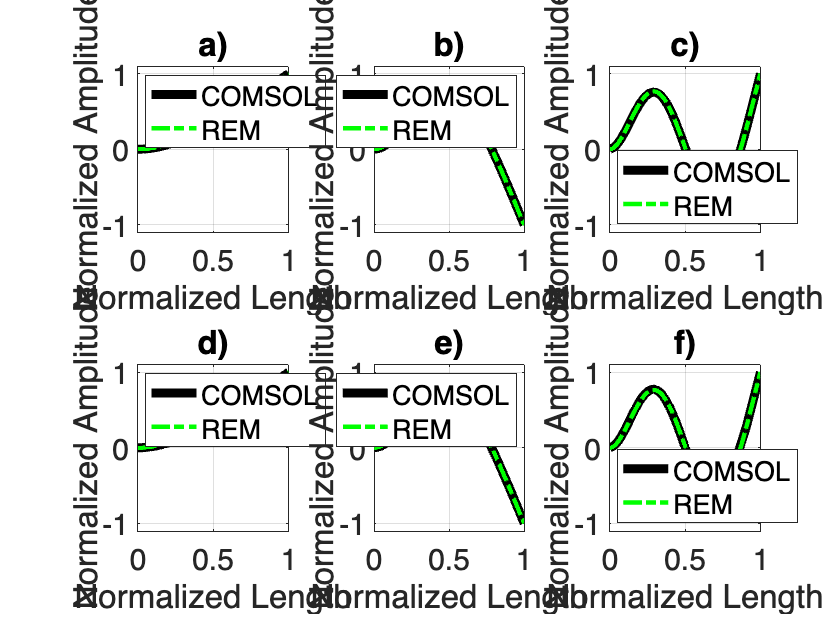

plotCompare2(x2, phiH_n, phiD_n, x_phi_CH, phi_CH, x_phi_CD, phi_CD)

## Helper Functions

function [X,x_elem,x] = GetNonUniformXVals(dx,Lx)
% --- Spatial Parameters ---
% End location of each element along beam length
L_Locs = cumsum(Lx);
% Number of elements
M = numel(dx);

% --- Populate relevant x-values
% Instantiate variables
X = cell(1,M);              % Relative element length array
x_elem = cell(1,M);         % Element position over x
x = zeros(sum(Lx./dx),1);   % Position over length array
for mm = 1:M
    % Define the relative length of each element using the spatial
    % resolution of each element its length
    X{mm} = (0:dx(mm):Lx(mm)).';
    if mm == 1
        % Define the element position along x
        x_elem{mm} = X{mm}(1:end-1);
        % Index
        b = numel(X{mm})-1;
        % Populate the first 'b' points in x
        x(1:b) = X{mm}(1:end-1);
    else
        % Define the element position along x
        x_elem{mm} = (L_Locs(mm-1) :...
                            dx(mm) :...
                      L_Locs(mm)-dx(mm)).';
        % Indices
        a = b + 1;
        b = b + numel(x_elem{mm});
        % Populate 'x' from indices 'a' to 'b'
        x(a:b) = x_elem{mm};
    end
end
end

function plotCompare(x1, phi1_U,phi1_S, x2, phi2_U, phi2_S)
    % Line Widths
    lw1 = 6;
    lw2 = 3;

    figure
    subplot(2,3,1)
    plot(x2,phi2_U(:,1)/max(abs(phi2_U(:,1))),'k-',LineWidth=lw1)
    % plot(x2,phi2_U(:,1),'k-',LineWidth=lw1)
    hold on
    plot(x1,phi1_U(:,1)/max(abs(phi1_U(:,1))),'g-.',LineWidth=lw2)
    % plot(x1,phi1_U(:,1),'g-.',LineWidth=3)
    hold off
    ylim([-1.1,1.1])
    title('a)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northwest')
    
    subplot(2,3,2)
    plot(x2,phi2_U(:,2)/max(abs(phi2_U(:,2))),'k-',LineWidth=lw1)
    % plot(x2,phi2_U(:,2),'k-',LineWidth=lw1)
    hold on
    plot(x1,phi1_U(:,2)/max(abs(phi1_U(:,2))),'g-.',LineWidth=lw2)
    % plot(x1,phi1_U(:,2),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('b)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northeast')
    
    subplot(2,3,3)
    plot(x2,phi2_U(:,3)/max(abs(phi2_U(:,3))),'k-',LineWidth=lw1)
    % plot(x2,phi2_U(:,3),'k-',LineWidth=lw1)
    hold on
    plot(x1,phi1_U(:,3)/max(abs(phi1_U(:,3))),'g-.',LineWidth=lw2)
    % plot(x1,phi1_U(:,3),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('c)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='southwest')
    
    subplot(2,3,4)
    plot(x2,phi2_S(:,1)/max(abs(phi2_S(:,1))),'k-',LineWidth=lw1)
    % plot(x2,phi2_S(:,1),'k-',LineWidth=lw1)
    hold on
    plot(x1,phi1_S(:,1)/max(abs(phi1_S(:,1))),'g-.',LineWidth=lw2)
    % plot(x1,phi1_S(:,1),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('d)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northwest')
    
    subplot(2,3,5)
    plot(x2,phi2_S(:,2)/max(abs(phi2_S(:,2))),'k-',LineWidth=lw1)
    % plot(x2,phi2_S(:,2),'k-',LineWidth=lw1)
    hold on
    plot(x1,phi1_S(:,2)/max(abs(phi1_S(:,2))),'g-.',LineWidth=lw2)
    % plot(x1,phi1_S(:,2),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('e)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northeast')
    
    subplot(2,3,6)
    plot(x2,phi2_S(:,3)/max(abs(phi2_S(:,3))),'k-',LineWidth=lw1)
    % plot(x2,phi2_S(:,3),'k-',LineWidth=lw1)
    hold on
    plot(x1,phi1_S(:,3)/max(abs(phi1_S(:,3))),'g-.',LineWidth=lw2)
    % plot(x1,phi1_S(:,3),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('f)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='southwest')
end

function plotCompare2(xREM, phiH_REM, phiD_REM, xCH, phi_CH, xCD, phi_CD)
    % Line Widths
    lw1 = 6;
    lw2 = 3;

    figure
    subplot(2,3,1)
    plot(xCH,phi_CH(:,1)/max(abs(phi_CH(:,1))),'k-',LineWidth=lw1)
    hold on
    plot(xREM,phiH_REM(:,1)/max(abs(phiH_REM(:,1))),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('a)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northwest')
    
    subplot(2,3,2)
    plot(xCH,phi_CH(:,2)/max(abs(phi_CH(:,2))),'k-',LineWidth=lw1)
    hold on
    plot(xREM,phiH_REM(:,2)/max(abs(phiH_REM(:,2))),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('b)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northeast')
    
    subplot(2,3,3)
    plot(xCH,phi_CH(:,3)/max(abs(phi_CH(:,3))),'k-',LineWidth=lw1)
    hold on
    plot(xREM,phiH_REM(:,3)/max(abs(phiH_REM(:,3))),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('c)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='southwest')
    
    subplot(2,3,4)
    plot(xCD,phi_CD(:,1)/max(abs(phi_CD(:,1))),'k-',LineWidth=lw1)
    hold on
    plot(xREM,phiD_REM(:,1)/max(abs(phiD_REM(:,1))),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('d)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northwest')
    
    subplot(2,3,5)
    plot(xCD,phi_CD(:,2)/max(abs(phi_CD(:,2))),'k-',LineWidth=lw1)
    hold on
    plot(xREM,phiD_REM(:,2)/max(abs(phiD_REM(:,2))),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('e)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='northeast')
    
    subplot(2,3,6)
    plot(xCD,phi_CD(:,3)/max(abs(phi_CD(:,3))),'k-',LineWidth=lw1)
    hold on
    plot(xREM,phiD_REM(:,3)/max(abs(phiD_REM(:,3))),'g-.',LineWidth=lw2)
    hold off
    ylim([-1.1,1.1])
    title('f)')
    ylabel('Normalized Amplitude')
    xlabel('Normalized Length')
    legend('COMSOL','REM', Location='southwest')
end